clc; clear all; close all;
cd 'G:\Jiaxu Song\Ag_in_warter'
addpath 'G:\Jiaxu Flashdrive Backup\code\functions'

T = readtable('Ag in water CC600, 1VDC, with simulation.xlsx');

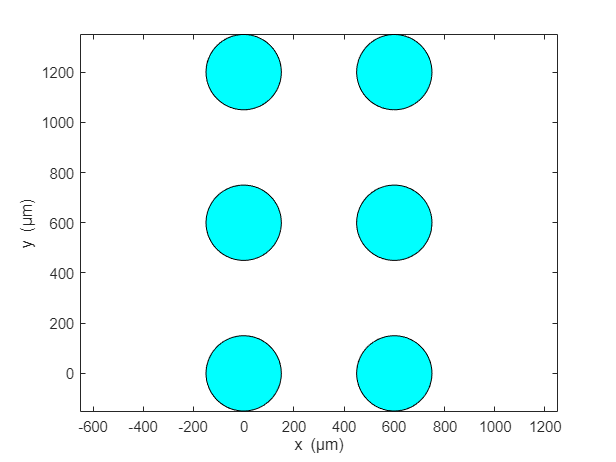

Lx = 600 ;%um
Ly = 600 ;% um
nooc = 2;
noor = 3;
padR = 150;% um
chipX = Lx * nooc;
chipY = Ly * noor;
h = plotChip(chipX,chipY,padR,nooc,noor);
axis equal
xlabel('x (\mum)')
ylabel('y (\mum)')
hold on

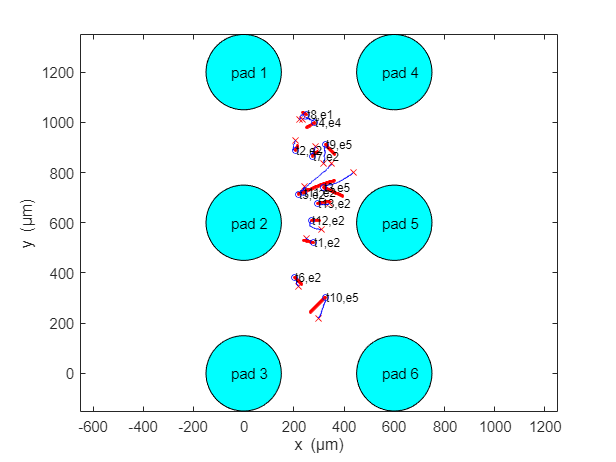

wire_num = 1;
electrode = [2 2 5 4 2 2 2 1 5 5 2 2 2];
for wire_num = 1:13

    str = electrode(wire_num);

    num = find(T.ID == wire_num);
    wire_out = [ones(length(num),1)*wire_num, T.expx_um_(num), T.expy_um_(num),...
        T.expz_um_(num), T.simx_um_(num), T.simy_um_(num), T.simz_um_(num)];
    plot3(wire_out(:,2),wire_out(:,3),wire_out(:,4),'b-'); hold on;
    plot3(wire_out(:,5),wire_out(:,6),wire_out(:,7),'r:.'); hold on;
    plot3(wire_out(1,2),wire_out(1,3),wire_out(1,4),'bo','MarkerSize',4); hold on;
    plot3(wire_out(end,2),wire_out(end,3),wire_out(end,4),'rx','MarkerSize',6); hold on;
    text(round(wire_out(1,2)+2),round(wire_out(1,3)+2),round(wire_out(1,4)),['t' num2str(wire_num) ',e' num2str(str)],'FontSize',8); hold on
%     legend('Experiment','Simulation')
end


text(-50,1200,0,('pad 1'),'FontSize',10); hold on
text(-50,600,0,['pad 2'],'FontSize',10); hold on
text(-50,0,0,['pad 3'],'FontSize',10); hold on
text(550,1200,0,['pad 4'],'FontSize',10); hold on
text(550,600,0,['pad 5'],'FontSize',10); hold on
text(550,0,0,['pad 6'],'FontSize',10); hold on


hold off